h = 0.01;
A = 750000;
i = 0;
aprox = zeros(1,3041);
r = 0.05;
time = 0;
while A > 0
    aprox(i+1) = A;
    ap = r * A - 12 * 4000;
    A = A + h * ap;
    i = i + 1;
    time = time + h;
end

intpay = 7.0940e+05

aprox(i+1) = A

aprox = 	1.0e+05 *

    7.5000    7.4989    7.4979    7.4968    7.4958    7.4947    7.4937    7.4926    7.4916    7.4905    7.4895    7.4884    7.4874    7.4863    7.4853    7.4842    7.4831    7.4821    7.4810    7.4800    7.4789    7.4778    7.4768    7.4757    7.4747    7.4736    7.4725    7.4715    7.4704    7.4693    7.4683    7.4672    7.4661    7.4651    7.4640    7.4629    7.4619    7.4608    7.4597    7.4587    7.4576    7.4565    7.4554    7.4544    7.4533    7.4522    7.4512    7.4501    7.4490    7.4479


aprox

aprox = 	1.0e+05 *

    7.5000    7.4989    7.4979    7.4968    7.4958    7.4947    7.4937    7.4926    7.4916    7.4905    7.4895    7.4884    7.4874    7.4863    7.4853    7.4842    7.4831    7.4821    7.4810    7.4800    7.4789    7.4778    7.4768    7.4757    7.4747    7.4736    7.4725    7.4715    7.4704    7.4693    7.4683    7.4672    7.4661    7.4651    7.4640    7.4629    7.4619    7.4608    7.4597    7.4587    7.4576    7.4565    7.4554    7.4544    7.4533    7.4522    7.4512    7.4501    7.4490    7.4479


A

A = -282.5196

i

i = 3041

time

time = 30.4100

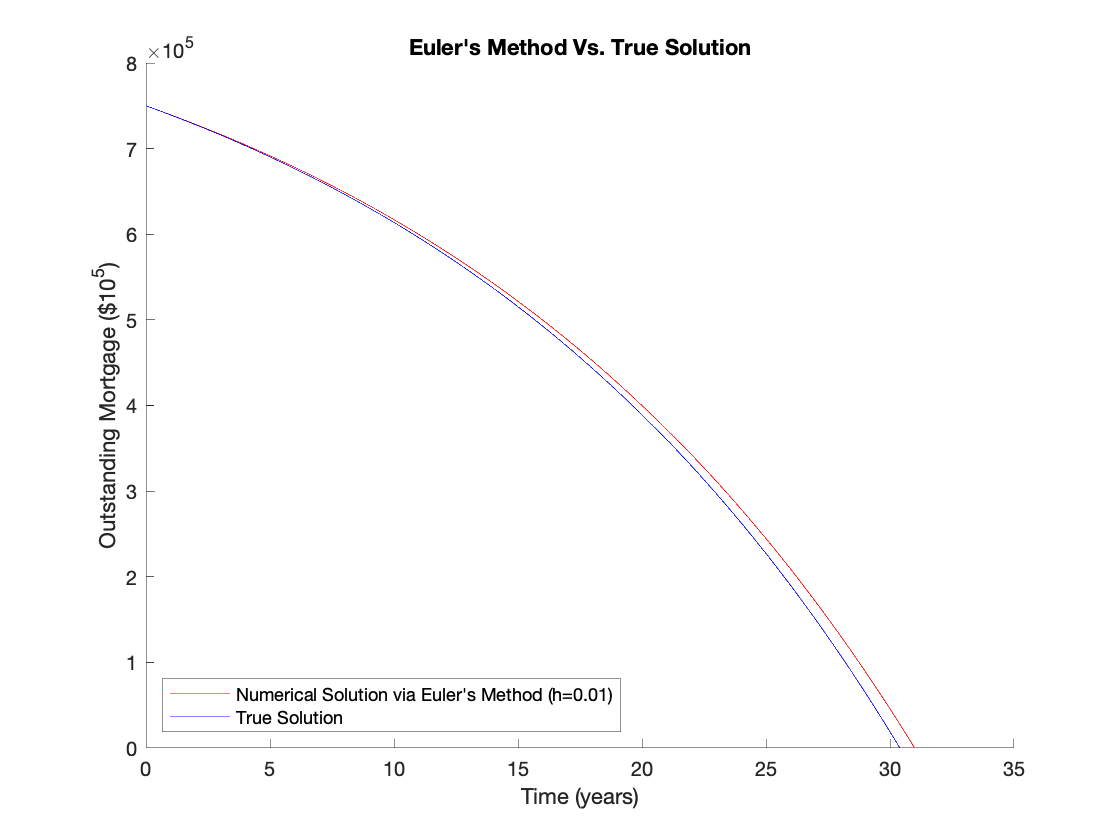

figure;
title("Euler's Method Vs. True Solution")
ts = linspace(0,31,3042);
hold on
plot(ts,aprox,'r',ts,960000-210000*exp(0.05.*ts),'b')
legend("Numerical Solution via Euler's Method (h=0.01)","True Solution","location", "southwest")
xlabel("Time (years)")
ylabel("Outstanding Mortgage ($10^5)")
ylim([0 8e5])
hold off